Constants for FFT

Fs = 1 / 0.001;

cd("C:\DavidZaha\Programming\Vanderbilt\sysphys\headphone-eeg-comparison\filtered_data")

files = dir('*.csv');

% Initialize a structure array to store results
EEG_Analyzed_Data = struct();

%column 1: right parietal
%column 2: central
%column 3: right frontal
%column 4: left temporal

for i = 1:length(files)
    filename = files(i).name;
    
  
    
    [~, name, ~] = fileparts(filename);
    parts = split(name, '_');            
    subject = parts{1}
    experiment = parts{2};
    
    data = readtable(filename);
    
    
    time = data{:, 1};       
    electrode1 = data{:, 2}; 
    electrode2 = data{:, 3};  
    electrode3 = data{:, 4};  
    electrode4 = data{:, 5};  
    

  
    Y1 = fft(electrode1);
    Y2 = fft(electrode2);
    Y3 = fft(electrode3);
    Y4 = fft(electrode4);
    
    N = length(Y1);

    disp(['subject: ', subject, ' experiment: ', experiment, ' length: ', num2str(N)]);
    EEG_Analyzed_Data.(subject).(experiment).right_parietal = abs(Y1(1:floor(N/2)));
    EEG_Analyzed_Data.(subject).(experiment).central = abs(Y2(1:floor(N/2)));
    EEG_Analyzed_Data.(subject).(experiment).right_frontal = abs(Y3(1:floor(N/2)));
    EEG_Analyzed_Data.(subject).(experiment).left_temporal = abs(Y4(1:floor(N/2)));

    
end

subject = 's01'

subject: s01 experiment: ex05 length: 24000


subject = 's01'

subject: s01 experiment: ex06 length: 24000


subject = 's01'

subject: s01 experiment: ex07 length: 24000


subject = 's01'

subject: s01 experiment: ex08 length: 24000


subject = 's01'

subject: s01 experiment: ex09 length: 24000


subject = 's01'

subject: s01 experiment: ex10 length: 24000


subject = 's02'

subject: s02 experiment: ex05 length: 24000


subject = 's02'

subject: s02 experiment: ex06 length: 24000


subject = 's02'

subject: s02 experiment: ex07 length: 24000


subject = 's02'

subject: s02 experiment: ex08 length: 24000


subject = 's02'

subject: s02 experiment: ex09 length: 24000


subject = 's02'

subject: s02 experiment: ex10 length: 24000


subject = 's03'

subject: s03 experiment: ex05 length: 24000


subject = 's03'

subject: s03 experiment: ex06 length: 23904


subject = 's03'

subject: s03 experiment: ex07 length: 44164


subject = 's03'

subject: s03 experiment: ex08 length: 24000


subject = 's03'

subject: s03 experiment: ex09 length: 24000


subject = 's03'

subject: s03 experiment: ex10 length: 24000


subject = 's04'

subject: s04 experiment: ex05 length: 24000


subject = 's04'

subject: s04 experiment: ex06 length: 24000


subject = 's04'

subject: s04 experiment: ex07 length: 24000


subject = 's04'

subject: s04 experiment: ex08 length: 24000


subject = 's04'

subject: s04 experiment: ex09 length: 24000


subject = 's04'

subject: s04 experiment: ex10 length: 24000


subject = 's05'

subject: s05 experiment: ex05 length: 40114


subject = 's05'

subject: s05 experiment: ex06 length: 24000


subject = 's05'

subject: s05 experiment: ex07 length: 24000


subject = 's05'

subject: s05 experiment: ex08 length: 24000


subject = 's05'

subject: s05 experiment: ex09 length: 24000


subject = 's05'

subject: s05 experiment: ex10 length: 24000


subject = 's06'

subject: s06 experiment: ex05 length: 24000


subject = 's06'

subject: s06 experiment: ex06 length: 24000


subject = 's06'

subject: s06 experiment: ex07 length: 24000


subject = 's06'

subject: s06 experiment: ex08 length: 24000


subject = 's06'

subject: s06 experiment: ex09 length: 24000


subject = 's06'

subject: s06 experiment: ex10 length: 24000


subject = 's07'

subject: s07 experiment: ex05 length: 24000


subject = 's07'

subject: s07 experiment: ex06 length: 24000


subject = 's07'

subject: s07 experiment: ex07 length: 24000


subject = 's07'

subject: s07 experiment: ex08 length: 24000


subject = 's07'

subject: s07 experiment: ex09 length: 24000


subject = 's07'

subject: s07 experiment: ex10 length: 24000


subject = 's08'

subject: s08 experiment: ex05 length: 24000


subject = 's08'

subject: s08 experiment: ex06 length: 24000


subject = 's08'

subject: s08 experiment: ex07 length: 24000


subject = 's08'

subject: s08 experiment: ex08 length: 24000


subject = 's08'

subject: s08 experiment: ex09 length: 24000


subject = 's08'

subject: s08 experiment: ex10 length: 24000


subject = 's09'

subject: s09 experiment: ex05 length: 24000


subject = 's09'

subject: s09 experiment: ex06 length: 24000


subject = 's09'

subject: s09 experiment: ex07 length: 24000


subject = 's09'

subject: s09 experiment: ex08 length: 24000


subject = 's09'

subject: s09 experiment: ex09 length: 24000


subject = 's09'

subject: s09 experiment: ex10 length: 24000


subject = 's10'

subject: s10 experiment: ex05 length: 24000


subject = 's10'

subject: s10 experiment: ex06 length: 24000


subject = 's10'

subject: s10 experiment: ex07 length: 24000


subject = 's10'

subject: s10 experiment: ex08 length: 24000


subject = 's10'

subject: s10 experiment: ex09 length: 24000


subject = 's10'

subject: s10 experiment: ex10 length: 24000


subject = 's11'

subject: s11 experiment: ex05 length: 24000


subject = 's11'

subject: s11 experiment: ex06 length: 24000


subject = 's11'

subject: s11 experiment: ex07 length: 24000


subject = 's11'

subject: s11 experiment: ex08 length: 24000


subject = 's11'

subject: s11 experiment: ex09 length: 24000


subject = 's11'

subject: s11 experiment: ex10 length: 24000


subject = 's12'

subject: s12 experiment: ex05 length: 24000


subject = 's12'

subject: s12 experiment: ex06 length: 24000


subject = 's12'

subject: s12 experiment: ex07 length: 24000


subject = 's12'

subject: s12 experiment: ex08 length: 24000


subject = 's12'

subject: s12 experiment: ex09 length: 24000


subject = 's12'

subject: s12 experiment: ex10 length: 24000


subject = 's13'

subject: s13 experiment: ex05 length: 24000


subject = 's13'

subject: s13 experiment: ex06 length: 24000


subject = 's13'

subject: s13 experiment: ex07 length: 24000


subject = 's13'

subject: s13 experiment: ex08 length: 24000


subject = 's13'

subject: s13 experiment: ex09 length: 24000


subject = 's13'

subject: s13 experiment: ex10 length: 24000


subject = 's14'

subject: s14 experiment: ex05 length: 24000


subject = 's14'

subject: s14 experiment: ex06 length: 24000


subject = 's14'

subject: s14 experiment: ex07 length: 24000


subject = 's14'

subject: s14 experiment: ex08 length: 24000


subject = 's14'

subject: s14 experiment: ex09 length: 24000


subject = 's14'

subject: s14 experiment: ex10 length: 24000


subject = 's15'

subject: s15 experiment: ex05 length: 24000


subject = 's15'

subject: s15 experiment: ex06 length: 24000


subject = 's15'

subject: s15 experiment: ex07 length: 24000


subject = 's15'

subject: s15 experiment: ex08 length: 24000


subject = 's15'

subject: s15 experiment: ex09 length: 24000


subject = 's15'

subject: s15 experiment: ex10 length: 24000


subject = 's16'

subject: s16 experiment: ex05 length: 24000


subject = 's16'

subject: s16 experiment: ex06 length: 24000


subject = 's16'

subject: s16 experiment: ex07 length: 24000


subject = 's16'

subject: s16 experiment: ex08 length: 24000


subject = 's16'

subject: s16 experiment: ex09 length: 24000


subject = 's16'

subject: s16 experiment: ex10 length: 24000


subject = 's17'

subject: s17 experiment: ex05 length: 24000


subject = 's17'

subject: s17 experiment: ex06 length: 24000


subject = 's17'

subject: s17 experiment: ex07 length: 24000


subject = 's17'

subject: s17 experiment: ex08 length: 24000


subject = 's17'

subject: s17 experiment: ex09 length: 24000


subject = 's17'

subject: s17 experiment: ex10 length: 28090


subject = 's18'

subject: s18 experiment: ex05 length: 24000


subject = 's18'

subject: s18 experiment: ex06 length: 24000


subject = 's18'

subject: s18 experiment: ex07 length: 24000


subject = 's18'

subject: s18 experiment: ex08 length: 24000


subject = 's18'

subject: s18 experiment: ex09 length: 24000


subject = 's18'

subject: s18 experiment: ex10 length: 24000


subject = 's19'

subject: s19 experiment: ex05 length: 24000


subject = 's19'

subject: s19 experiment: ex06 length: 24000


subject = 's19'

subject: s19 experiment: ex07 length: 24000


subject = 's19'

subject: s19 experiment: ex08 length: 24000


subject = 's19'

subject: s19 experiment: ex09 length: 24000


subject = 's19'

subject: s19 experiment: ex10 length: 24000


subject = 's20'

subject: s20 experiment: ex05 length: 24000


subject = 's20'

subject: s20 experiment: ex06 length: 24000


subject = 's20'

subject: s20 experiment: ex07 length: 24000


subject = 's20'

subject: s20 experiment: ex08 length: 24000


subject = 's20'

subject: s20 experiment: ex09 length: 24000


subject = 's20'

subject: s20 experiment: ex10 length: 24000


% accessing data from the struct
% EEG_Analyzed_Data.s01.ex05.right_frontal

disp(EEG_Analyzed_Data.s01.ex10)


Plotting accross electrodes for one subject and experiment

smoothing

Triangular filter (4, 2, 1)

average of nearest neighbors

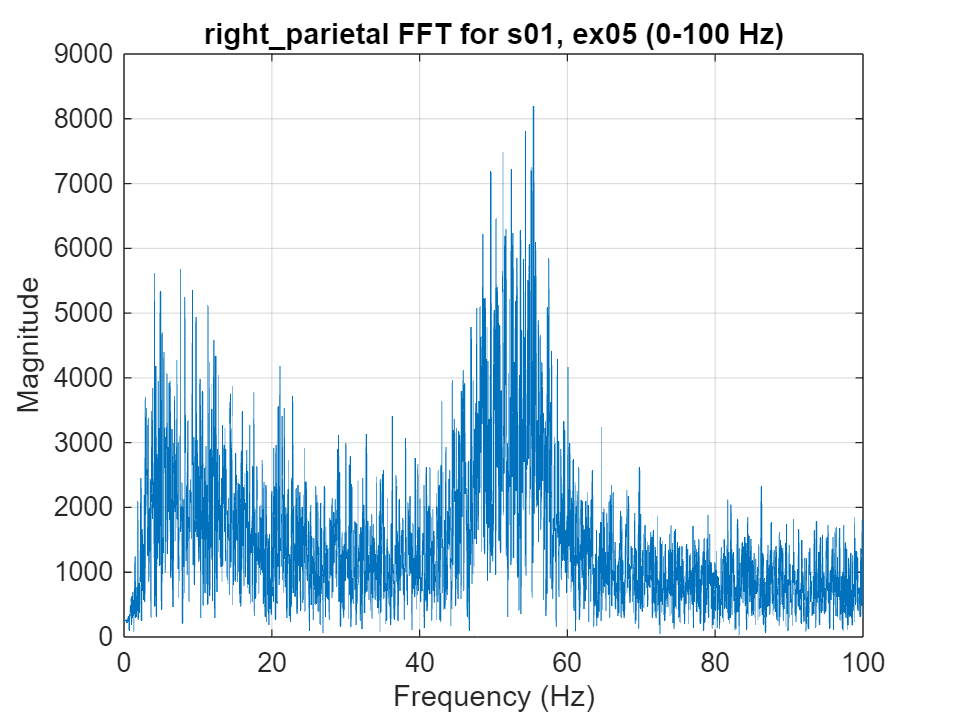

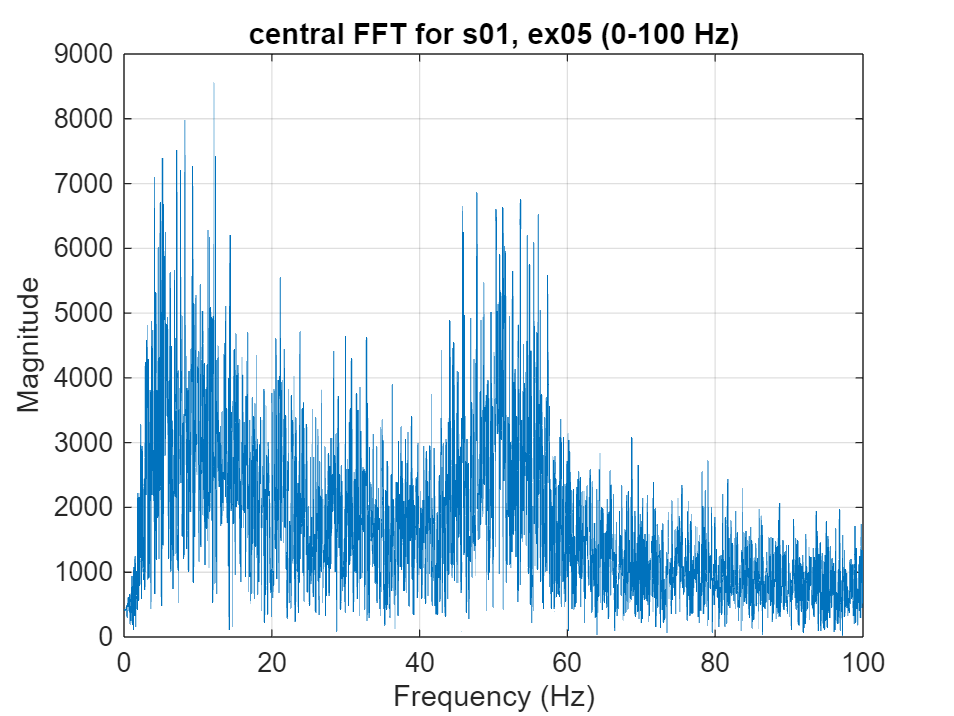

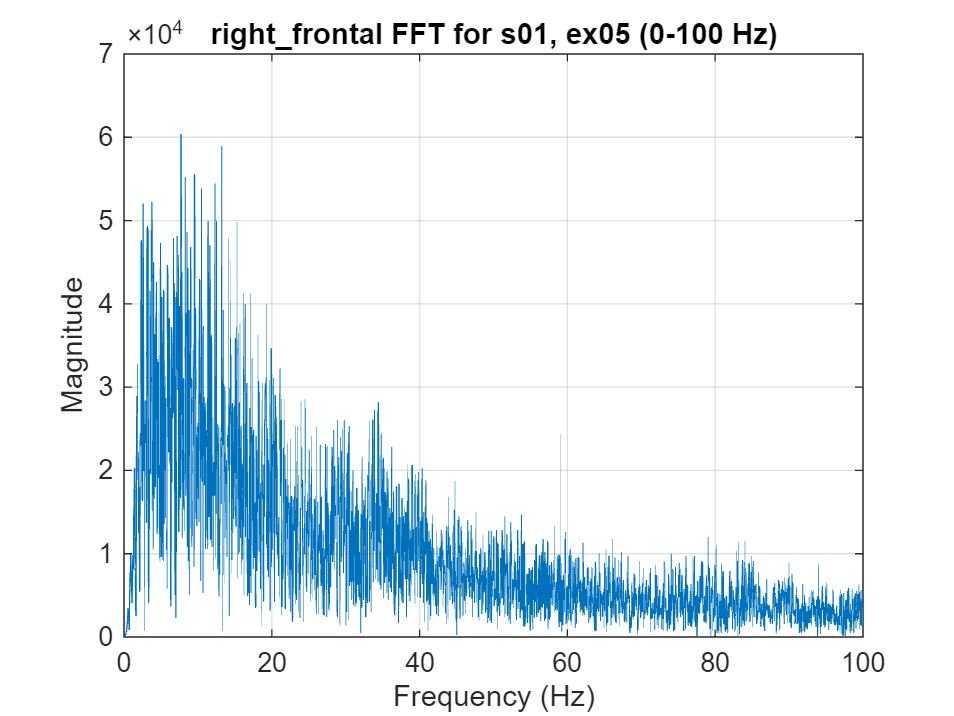

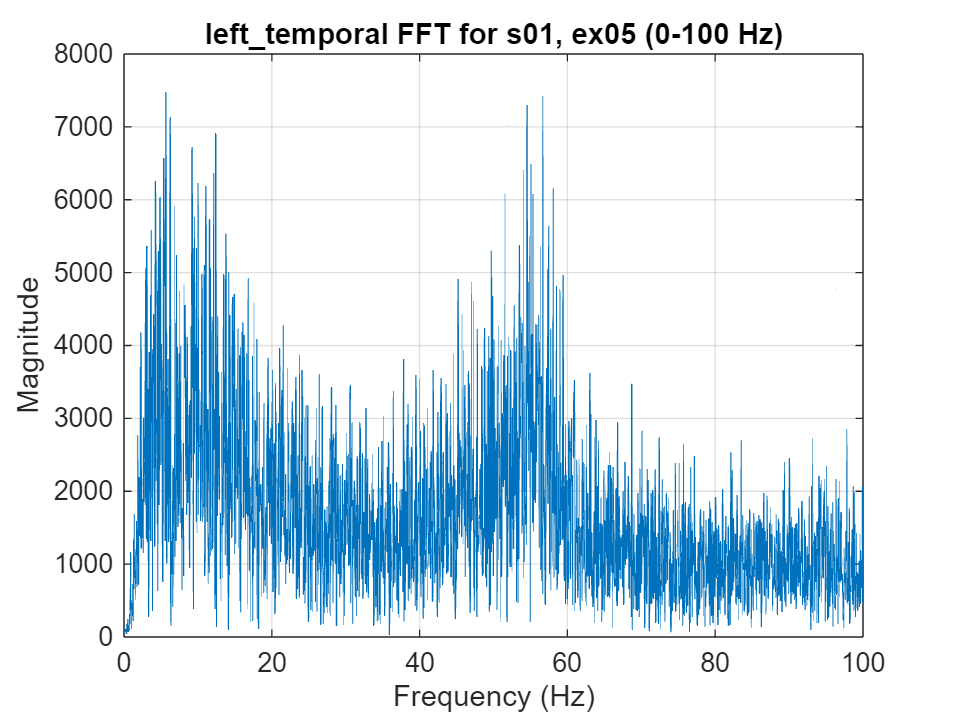

subject = 's01';  
experiment = 'ex05';
fftData = EEG_Analyzed_Data.(subject).(experiment);


N = length(fftData.right_parietal); 
f = (0:N-1)*(Fs/(2*N));

fields = fieldnames(fftData);


for i = 1:numel(fields)
    
    Y = fftData.(fields{i});
    
    
    figure;
    plot(f, Y);
    title([fields{i}, ' FFT for ', subject, ', ', experiment, ' (0-100 Hz)'], 'Interpreter', 'none');
    xlabel('Frequency (Hz)');
    xlim([0,100])
    ylabel('Magnitude');
    grid on;
end

Plotting accross experiments for one subject and one electrode

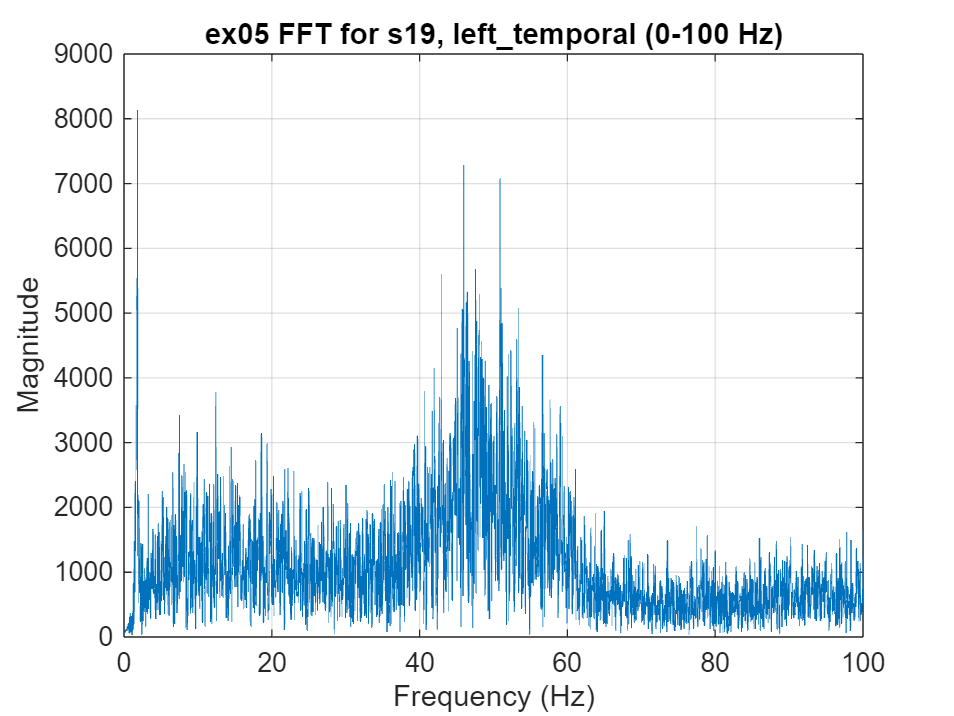

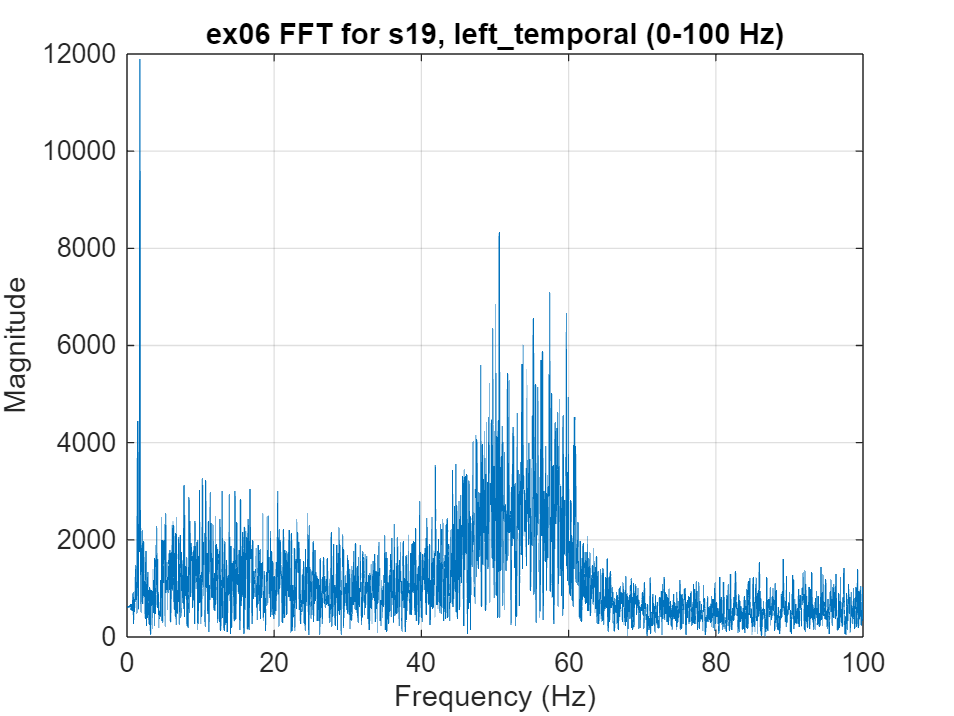

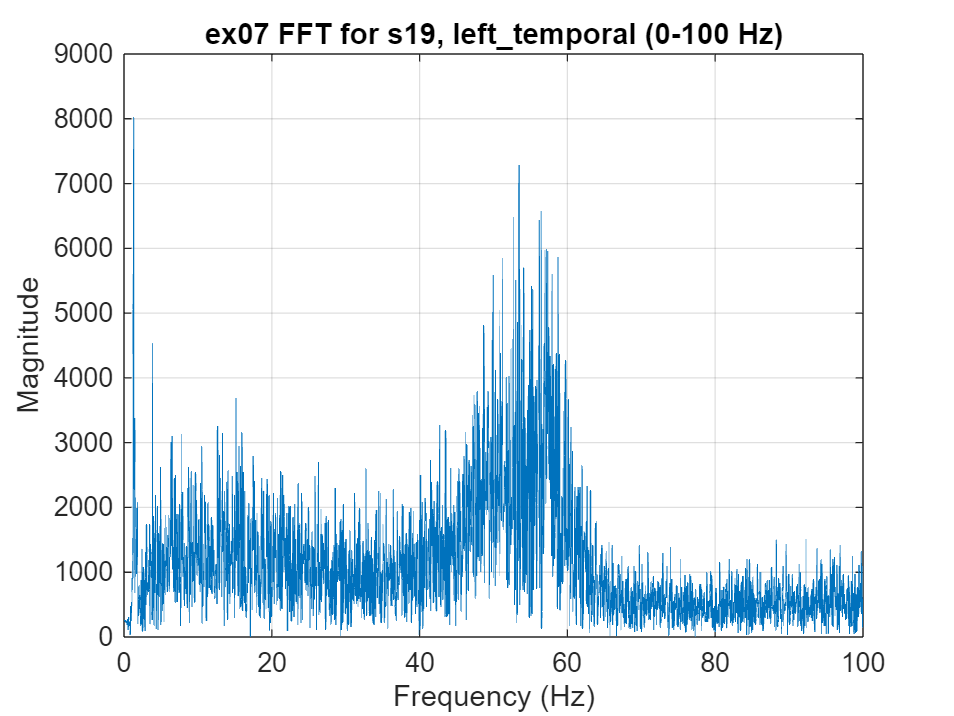

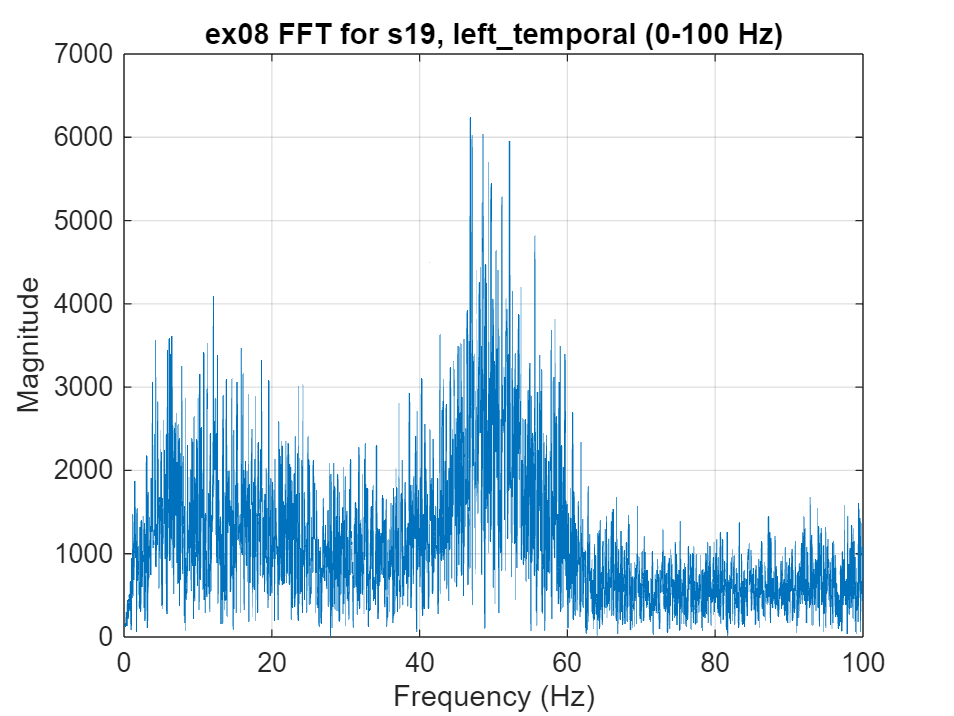

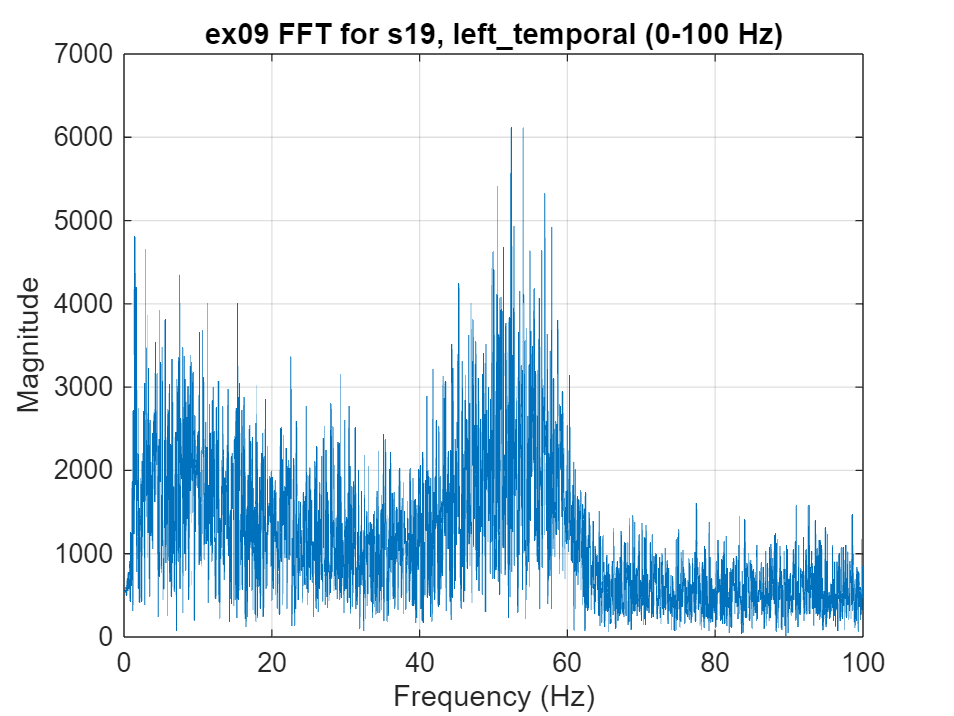

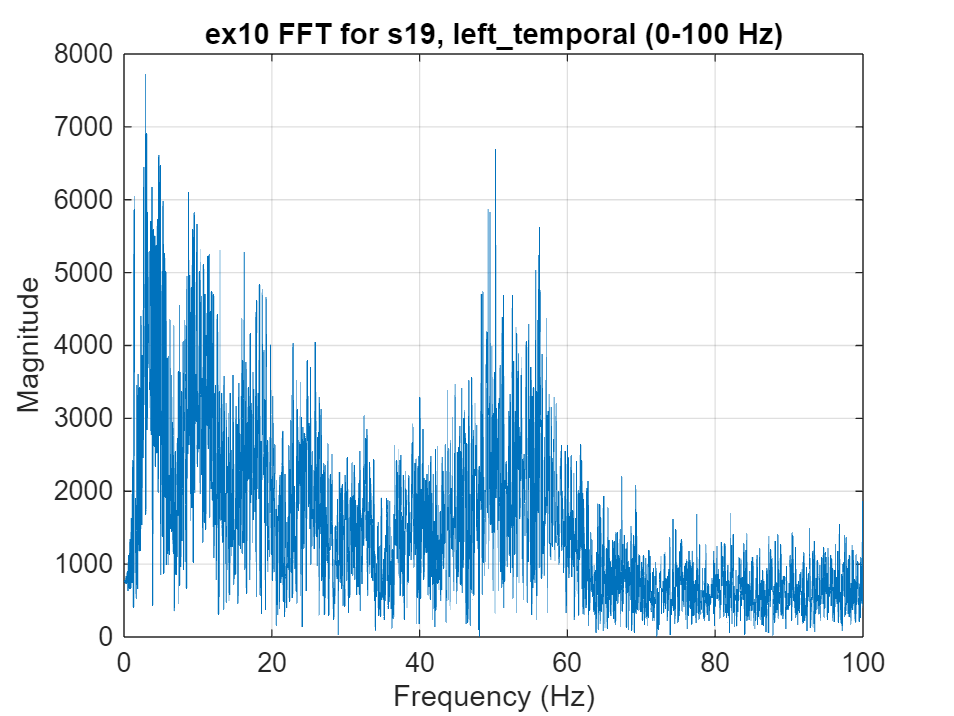

subject = 's19';  
electrode = 'left_temporal';
fftData = EEG_Analyzed_Data.(subject).(experiment);


experiments = fieldnames(EEG_Analyzed_Data.(subject));

for i = 1:numel(experiments)
    
    experiment = experiments{i};
    Y = EEG_Analyzed_Data.(subject).(experiment).(electrode);

    N = length(Y); 
    f = (0:N-1)*(Fs/(2*N));
    
    figure;
    plot(f, Y);
    title([experiment, ' FFT for ', subject, ', ', electrode, ' (0-100 Hz)'], 'Interpreter', 'none');
    xlabel('Frequency (Hz)');
    xlim([0,100])
    ylabel('Magnitude');
    grid on;
end

## Statistical Analysis

%for reference
% [h p ci stats] = ttest(EEG_Analyzed_Data.s01.ex05.left_temporal, EEG_Analyzed_Data.s01.ex08.left_temporal);

subjects = fieldnames(EEG_Analyzed_Data);
experiments = fieldnames(EEG_Analyzed_Data.s01);

lobes = fieldnames(EEG_Analyzed_Data.s01.ex05);



in_ear_averages = cell(4,20); 
%column 1: right parietal
%column 2: central
%column 3: right frontal
%column 4: left temporal

%This loop takes the average of the data for the in ear headphone
%experiments (5,6,7) for each subject and lobe recording, adding it to the
%cell created above
for i = 1:numel(subjects)
    for j = 1:numel(lobes)
         if (length(EEG_Analyzed_Data.(subjects{i}).ex05.(lobes{j}))==12000 && ... 
                 length(EEG_Analyzed_Data.(subjects{i}).ex06.(lobes{j}))==12000 && ...
                       length(EEG_Analyzed_Data.(subjects{i}).ex07.(lobes{j}))==12000)
         %some recordings have different dataset sizes (subjects 3 and 5),
         %so this if statement eliminates them
         in_ear_averages{j,i} = (EEG_Analyzed_Data.(subjects{i}).ex05.(lobes{j}) + EEG_Analyzed_Data.(subjects{i}).ex06.(lobes{j}) + EEG_Analyzed_Data.(subjects{i}).ex07.(lobes{j}))/3;
         end
    end
end
disp(in_ear_averages)

    {12000×1 double}    {12000×1 double}    {0×0 double}    {12000×1 double}    {0×0 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}
    {12000×1 double}    {12000×1 double}    {0×0 double}    {12000×1 double}    {0×0 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}
    {12000×1 double}    {12000×1 double}    {0×0 double}    {12000×1 double}    {0×0 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}  

bone_conduction_averages = cell(4,20);
%column 1: right parietal
%column 2: central
%column 3: right frontal
%column 4: left temporal

for i = 1:numel(subjects)
    for j = 1:numel(lobes)
         if (length(EEG_Analyzed_Data.(subjects{i}).ex08.(lobes{j}))==12000 && ... 
                 length(EEG_Analyzed_Data.(subjects{i}).ex09.(lobes{j}))==12000 && ...
                       length(EEG_Analyzed_Data.(subjects{i}).ex10.(lobes{j}))==12000)
         %some recordings have different dataset sizes (subjects 3 and 5),
         %so this if statement eliminates them
         bone_conduction_averages{j,i} = (EEG_Analyzed_Data.(subjects{i}).ex08.(lobes{j}) + EEG_Analyzed_Data.(subjects{i}).ex09.(lobes{j}) + EEG_Analyzed_Data.(subjects{i}).ex10.(lobes{j}))/3;
         end
    end
end
disp(bone_conduction_averages)

    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {0×0 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}
    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {0×0 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}
    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {1

    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {0×0 double}    {12000×1 double}    {0×0 double}    {0×0 double}
    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {0×0 double}    {12000×1 double}    {0×0 double}    {0×0 double}
    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}    {12000×1 double}  

in_ear_alpha = zeros(4,20);
in_ear_beta = zeros(4,20);
in_ear_gamma = zeros(4,20);


for i = 1:numel(subjects)
    for j = 1:numel(lobes)
        if length(in_ear_averages{j,i})==12000
            wave = in_ear_averages{j,i};
            total_mean = mean(wave(192:1440))
            in_ear_alpha(j,i) = mean(wave([192:288]))/total_mean;
            in_ear_beta(j,i) = mean(wave([288:720]))/total_mean;
            in_ear_gamma(j,i) = mean(wave([720:1440]))/total_mean;
        end
    end
end

total_mean = 1.9923e+03

total_mean = 2.1409e+03

total_mean = 8.7045e+03

total_mean = 1.9349e+03

total_mean = 4.1481e+03

total_mean = 3.4255e+03

total_mean = 3.7699e+03

total_mean = 3.8203e+03

total_mean = 1.8184e+03

total_mean = 1.5699e+03

total_mean = 1.4157e+03

total_mean = 1.4707e+03

total_mean = 2.0725e+03

total_mean = 2.0081e+03

total_mean = 1.9119e+03

total_mean = 1.5139e+03

total_mean = 1.7400e+03

total_mean = 2.0764e+03

total_mean = 1.7920e+03

total_mean = 1.7102e+03

total_mean = 2.6249e+03

total_mean = 1.6896e+03

total_mean = 1.7674e+03

total_mean = 1.5981e+03

total_mean = 2.9449e+03

total_mean = 1.6880e+03

total_mean = 1.5517e+03

total_mean = 1.8094e+03

total_mean = 2.9238e+03

total_mean = 1.9387e+03

total_mean = 1.6627e+03

total_mean = 2.2664e+03

total_mean = 1.5439e+03

total_mean = 1.4215e+03

total_mean = 1.6371e+03

total_mean = 1.5625e+03

total_mean = 2.0467e+03

total_mean = 1.8954e+03

total_mean = 1.4836e+03

total_mean = 1.7899e+03

total_mean = 1.8686e+03

total_mean = 1.7975e+03

total_mean = 1.8715e+03

total_mean = 1.4211e+03

total_mean = 1.2262e+03

total_mean = 1.7732e+03

total_mean = 1.4856e+03

total_mean = 1.1422e+03

total_mean = 2.6218e+03

total_mean = 2.2261e+03

total_mean = 1.7393e+03

total_mean = 1.9043e+03

total_mean = 1.4308e+03

total_mean = 1.1817e+03

total_mean = 1.3127e+03

total_mean = 1.0234e+03

total_mean = 913.8992

total_mean = 1.3565e+03

total_mean = 1.2124e+03

total_mean = 983.8333

total_mean = 1.8824e+03

total_mean = 2.5462e+03

total_mean = 1.7139e+03

total_mean = 1.9992e+03

total_mean = 1.9108e+03

total_mean = 1.5398e+03

total_mean = 1.5117e+03

total_mean = 1.5192e+03

total_mean = 1.5276e+03

total_mean = 1.4602e+03

total_mean = 1.4044e+03

total_mean = 1.4320e+03

disp(in_ear_gamma)

    1.1012    0.7233         0    1.0944         0    1.3066    1.2044    1.3608    1.3808    1.2923    1.2062    1.2567    1.1818    1.1537    1.2676    1.2316    1.0327    1.2882    1.2687    0.8907
    0.9862    0.6599         0    0.9449         0    1.2029    1.1789    1.0816    1.1364    1.1087    1.1254    1.1568    1.0405    1.0890    1.1316    0.9112    1.0578    1.3155    1.0515    0.7727
    0.6818    0.5582         0    0.9305         0    1.0696    1.1065    1.0215    1.1450    1.0859    1.0723    1.1352    0.9486    1.0906    1.0425    0.7652    0.9758    1.2351    0.9898    0.8116
    0.9978    0.6465         0    0.8703         0    1.1960    1.1587    1.1396    1.2320    1.2166    1.0968    1.2199    1.0367    1.0636    1.1675    0.9778    1.0099    1.2379    1.1672    0.7806



bone_conduction_alpha = zeros(4,20);
bone_conduction_beta = zeros(4,20);
bone_conduction_gamma = zeros(4,20);


for i = 1:numel(subjects)
    for j = 1:numel(lobes)
        if length(bone_conduction_averages{j,i})==12000
            
            wave = bone_conduction_averages{j,i};
            total_mean = mean(wave(192:1440))
            bone_conduction_alpha(j,i) = mean(wave([192:288]))/total_mean;
            bone_conduction_beta(j,i) = mean(wave([288:720]))/total_mean;
            bone_conduction_gamma(j,i) = mean(wave([720:1440]))/total_mean;
        end
    end
end

total_mean = 3.4611e+03

total_mean = 3.8670e+03

total_mean = 4.8116e+03

total_mean = 3.7831e+03

total_mean = 2.4499e+03

total_mean = 2.1048e+03

total_mean = 2.8332e+03

total_mean = 2.2010e+03

total_mean = 1.2434e+03

total_mean = 1.2181e+03

total_mean = 1.3276e+03

total_mean = 1.3232e+03

total_mean = 1.7022e+03

total_mean = 1.4708e+03

total_mean = 1.3054e+03

total_mean = 1.2025e+03

total_mean = 3.0662e+03

total_mean = 2.6077e+03

total_mean = 2.6307e+03

total_mean = 2.6814e+03

total_mean = 2.2160e+03

total_mean = 2.0405e+03

total_mean = 2.0272e+03

total_mean = 1.4505e+03

total_mean = 1.5371e+03

total_mean = 1.9045e+03

total_mean = 1.5756e+03

total_mean = 1.5052e+03

total_mean = 2.5832e+03

total_mean = 1.6832e+03

total_mean = 1.7006e+03

total_mean = 1.5778e+03

total_mean = 2.8238e+03

total_mean = 1.6322e+03

total_mean = 1.5001e+03

total_mean = 1.7630e+03

total_mean = 2.7649e+03

total_mean = 1.9169e+03

total_mean = 1.5956e+03

total_mean = 2.2211e+03

total_mean = 1.4422e+03

total_mean = 1.3317e+03

total_mean = 1.5547e+03

total_mean = 1.4405e+03

total_mean = 2.2140e+03

total_mean = 1.9949e+03

total_mean = 1.6434e+03

total_mean = 1.9452e+03

total_mean = 1.8281e+03

total_mean = 1.7103e+03

total_mean = 1.9733e+03

total_mean = 1.3657e+03

total_mean = 1.3035e+03

total_mean = 1.8089e+03

total_mean = 1.4770e+03

total_mean = 1.1851e+03

total_mean = 2.3491e+03

total_mean = 2.1410e+03

total_mean = 1.6342e+03

total_mean = 1.7897e+03

total_mean = 1.4897e+03

total_mean = 1.2275e+03

total_mean = 1.4144e+03

total_mean = 1.0790e+03

total_mean = 1.8305e+03

total_mean = 2.5877e+03

total_mean = 1.7444e+03

total_mean = 1.9936e+03

total_mean = 2.1427e+03

total_mean = 1.9853e+03

total_mean = 2.1442e+03

total_mean = 1.6644e+03

total_mean = 1.2355e+03

total_mean = 1.1761e+03

total_mean = 1.1927e+03

total_mean = 1.1677e+03

disp(bone_conduction_gamma)

    0.8646    1.1306    0.8571    1.2135    1.0477    1.2461    1.2144    1.3384    1.3497    1.3197    1.1859    1.1902    1.1623    1.1810    1.2132    1.2223         0    1.3066    1.1350    0.9542
    0.7719    0.9923    0.8137    1.0431    1.0672    1.2026    1.1567    1.0628    1.1195    1.1126    1.0918    1.0936    1.0170    1.1261    1.0643    0.9136         0    1.3372    0.8779    0.8317
    0.6900    0.7362    0.7873    1.0549    1.0236    1.0800    1.0839    1.0116    1.1353    1.1263    1.0262    1.0237    0.9304    1.0798    1.0067    0.8032         0    1.2377    0.8886    0.8459
    0.7658    1.0408    0.8385    1.0092    0.8126    1.1672    1.1616    1.1460    1.2271    1.2515    1.0750    1.1556    1.0001    1.0909    1.1171    0.9941         0    1.2582    1.0120    0.8358



disp(bone_conduction_alpha)

    1.3832    0.9806    0.8067    0.7478    0.8292    0.6625    0.5924    0.6697    0.7957    1.0470    0.9691    0.8567    0.8395    0.8684         0    0.6424    1.5077
    1.5279    1.0798    1.0897    0.7534    0.8634    0.8984    0.8817    0.9956    0.8830    1.2221    1.1105    0.8852    0.9968    1.3584         0    0.6008    1.8424
    2.1419    2.3317    1.1268    0.7799    1.1663    1.3029    0.9810    0.9498    1.0107    1.4017    1.1506    1.0114    1.1499    2.0848         0    0.8144    1.7622
    1.5390    1.0899    1.1577    1.3058    0.9154    0.9149    0.7147    0.7020    0.8798    1.1117    1.0713    0.8979    0.8844    1.2915         0    0.7102    1.7418



%removing subjects 3 and 5
in_ear_alpha(:,3) = [];
in_ear_beta(:,3) = [];
in_ear_gamma(:,3) = [];
in_ear_alpha(:,5-1) = [];
in_ear_beta(:,5-1) = [];
in_ear_gamma(:,5-1) = [];
in_ear_alpha(:,17-2) = [];
in_ear_beta(:,17-2) = [];
in_ear_gamma(:,17-2) = [];

bone_conduction_alpha(:,3) = [];
bone_conduction_beta(:,3) = [];
bone_conduction_gamma(:,3) = [];
bone_conduction_alpha(:,5-1) = [];
bone_conduction_beta(:,5-1) = [];
bone_conduction_gamma(:,5-1) = [];
bone_conduction_alpha(:,17-2) = [];
bone_conduction_beta(:,17-2) = [];
bone_conduction_gamma(:,17-2) = [];


%[h p ci stats] = ttest(bone_conduction_beta(4,:), in_ear_beta(4,:))

p_values = zeros(4,3);
stat_values = cell(4,3);

for i = 1:4
    for j = 1:3
        if j == 1
            [h p ci stats] = ttest(bone_conduction_alpha(i,:), in_ear_alpha(i,:));
            p_values(i,1) = p;
            stat_values{i,1} = stats;
        elseif j == 2
            [h p ci stats] = ttest(bone_conduction_beta(i,:), in_ear_beta(i,:));
            p_values(i,2) = p;
            stat_values{i,2} = stats;
        elseif j == 3
            [h p ci stats] = ttest(bone_conduction_gamma(i,:), in_ear_gamma(i,:));
            p_values(i,3) = p;
            stat_values{i,3} = stats;
        end
    end
end

disp(p_values)

    0.9266    0.9229    0.9725
    0.8645    0.8961    0.8700
    0.5322    0.5591    0.8102
    0.8485    0.8594    0.8497



disp(stat_values)

    {1×1 struct}    {1×1 struct}    {1×1 struct}
    {1×1 struct}    {1×1 struct}    {1×1 struct}
    {1×1 struct}    {1×1 struct}    {1×1 struct}
    {1×1 struct}    {1×1 struct}    {1×1 struct}



disp(stat_values{1,1})

    tstat: 0.0935
       df: 16
       sd: 0.3236



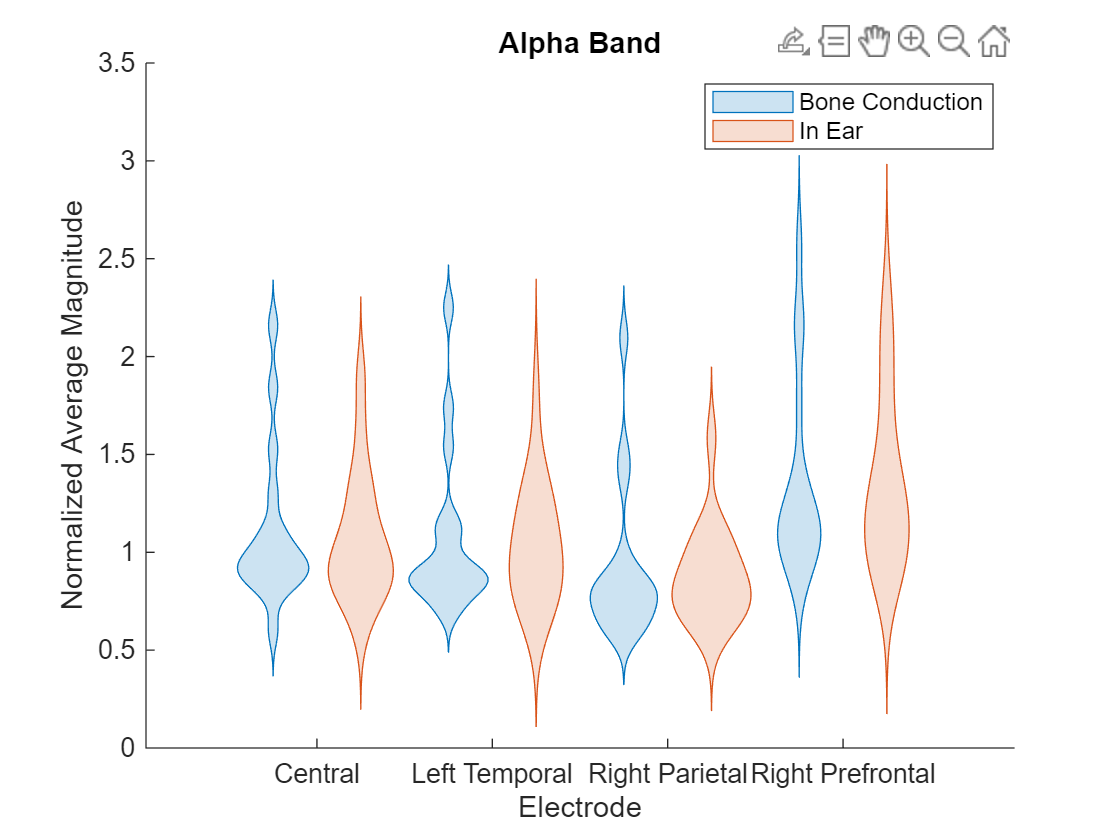

% Prepare the Data
Data_alpha = [
    bone_conduction_alpha(1,:)';
    in_ear_alpha(1,:)';
    bone_conduction_alpha(2,:)';
    in_ear_alpha(2,:)';
    bone_conduction_alpha(3,:)';
    in_ear_alpha(3,:)';
    bone_conduction_alpha(4,:)';
    in_ear_alpha(4,:)';
];

% Create electrode labels matching the data
Electrode_labels = [
    repmat("Right Parietal",34,1);    % Electrode 1
    repmat("Central",34,1);           % Electrode 2
    repmat("Right Prefrontal",34,1);  % Electrode 3
    repmat("Left Temporal",34,1);     % Electrode 4
];
Electrode_labels = categorical(Electrode_labels);

% Create measurement type labels matching the data
Measurement_labels = [
    repmat(["Bone Conduction"; "In Ear"],17,1);  % Electrode 1
    repmat(["Bone Conduction"; "In Ear"],17,1);  % Electrode 2
    repmat(["Bone Conduction"; "In Ear"],17,1);  % Electrode 3
    repmat(["Bone Conduction"; "In Ear"],17,1);  % Electrode 4
];
Measurement_labels = Measurement_labels(:);  % Flatten into a column vector
Measurement_labels = categorical(Measurement_labels);

% Plot the Violin Plot
figure;
violinplot(Electrode_labels, Data_alpha, 'GroupByColor', Measurement_labels);
xlabel('Electrode');
ylabel('Normalized Average Magnitude');
title('Alpha Band');
legend('Bone Conduction', 'In Ear');
ylim([0,3.5])

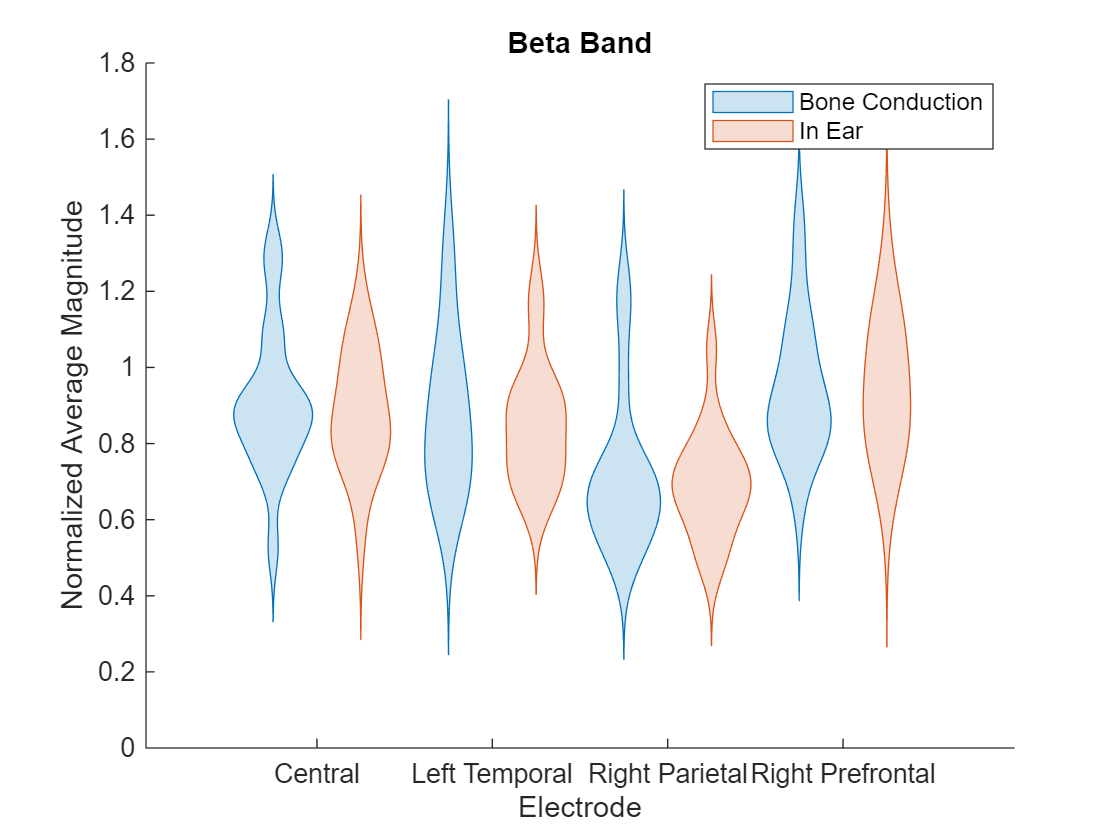



% Prepare data for Beta Band
Data_beta = [
    bone_conduction_beta(1,:)';
    in_ear_beta(1,:)';
    bone_conduction_beta(2,:)';
    in_ear_beta(2,:)';
    bone_conduction_beta(3,:)';
    in_ear_beta(3,:)';
    bone_conduction_beta(4,:)';
    in_ear_beta(4,:)';
];

% Plot Beta Band Violin Plot
figure;
violinplot( Electrode_labels,Data_beta, 'GroupByColor', Measurement_labels);
xlabel('Electrode');
ylabel('Normalized Average Magnitude');
title('Beta Band');
legend('Bone Conduction', 'In Ear');
ylim([0, 1.8])

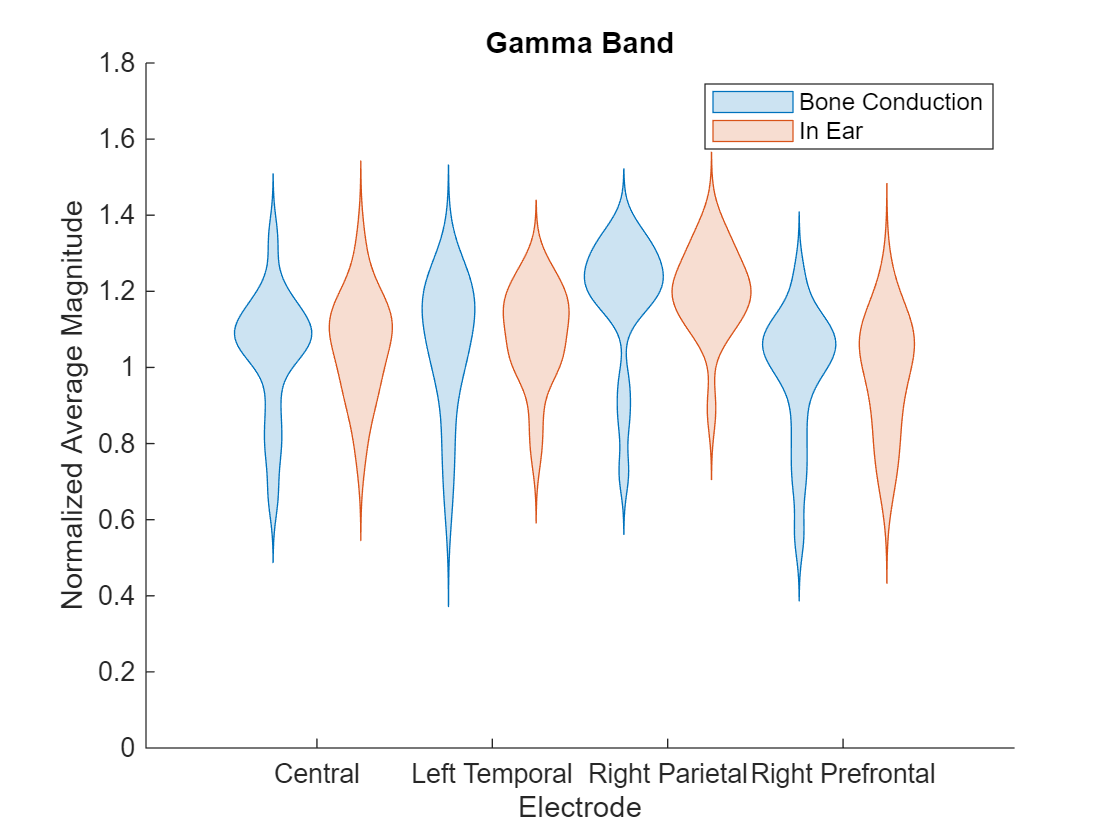


% Prepare data for Gamma Band
Data_gamma = [
    bone_conduction_gamma(1,:)';
    in_ear_gamma(1,:)';
    bone_conduction_gamma(2,:)';
    in_ear_gamma(2,:)';
    bone_conduction_gamma(3,:)';
    in_ear_gamma(3,:)';
    bone_conduction_gamma(4,:)';
    in_ear_gamma(4,:)';
];

% Plot Gamma Band Violin Plot
figure;
violinplot(Electrode_labels, Data_gamma, 'GroupByColor', Measurement_labels);
xlabel('Electrode');
ylabel('Normalized Average Magnitude');
title('Gamma Band');
legend('Bone Conduction', 'In Ear');
ylim([0, 1.8])